Spline

Aksel for dimentionering

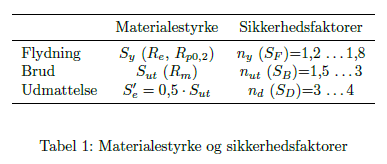

Case 4

 at yield

clear
clf
T_max = [10e3 10e3 1e3 0.1e3];% * K_a; %Nm

n_y = 2; 
S_y = 470; %375 - 460 % edu pack AISI 1080 normalized (similar AISI 4340 Steel, normalized in SW)

tau_til = 1/sqrt(3) * S_y / n_y % allowable stresses

tau_til = 135.6773

For hollow shaft

d = [42e-3 42e-3 33e-3 33e-3] ; % inner diameter
D_sol = zeros(1, length(T_max)); % stand ind for outer diameter
for i = 1:length(T_max)
    syms D
    W_p = pi * (D^4 - d(i)^4)/(16*D); %MMTH page 46 
    D_eq = tau_til*1e6 == T_max(i) / W_p; % setting up equation
    
    D_sol = solve(D_eq, D); %solving for outer diameter
    D_sols(i) = double(D_sol(4))
end

D_sols = 0.0747

D_sols =     0.0747    0.0747


D_sols =     0.0747    0.0747    0.0406


D_sols =     0.0747    0.0747    0.0406    0.0339



D = [82e-3 42e-3 42e-3];
d = [42e-3 33e-3 33e-3];
T_max = [10e3 1e3 0.1e3];
W_p = pi * (D.^4 - d.^4)./(16.*D)

W_p = 1.0e-03 *

    0.1008    0.0090    0.0090


tau = double(T_max ./ W_p) / 1e6

tau =    99.1966  111.0744   11.1074


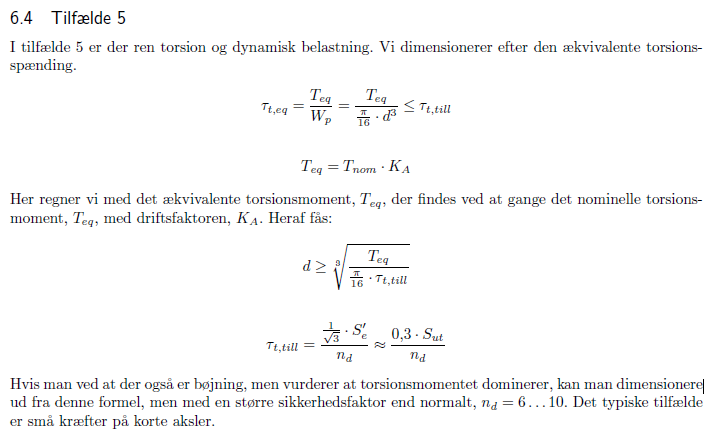

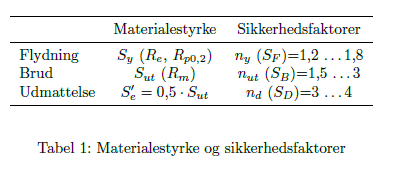

% K_a = 1.0; % tabel 2,3,4 and 5 in "Fordimensionering af aksler" % for dynamic forces
% S_ut = 600;
% n_d = 3
% 
% tau_til = 0.3 * S_ut / n_d
% 
% D_sol = zeros(1, length(T_max)); % stand ind for outer diameter
% for i = 1:length(T_max)
%     syms D
%     W_p = pi * (D^4 - d(i)^4)/(16*D); %MMTH page 46 
%     D_eq = tau_til*1e6 == T_max(i) / W_p; % setting up equation
% 
%     D_sol = solve(D_eq, D); %solving for outer diameter
%     D_sols(i) = double(D_sol(4));
% end
% 
% D_sols
% D_sols_mm = D_sols *1e3

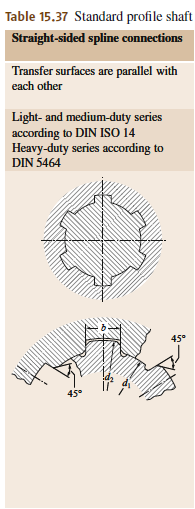Springers

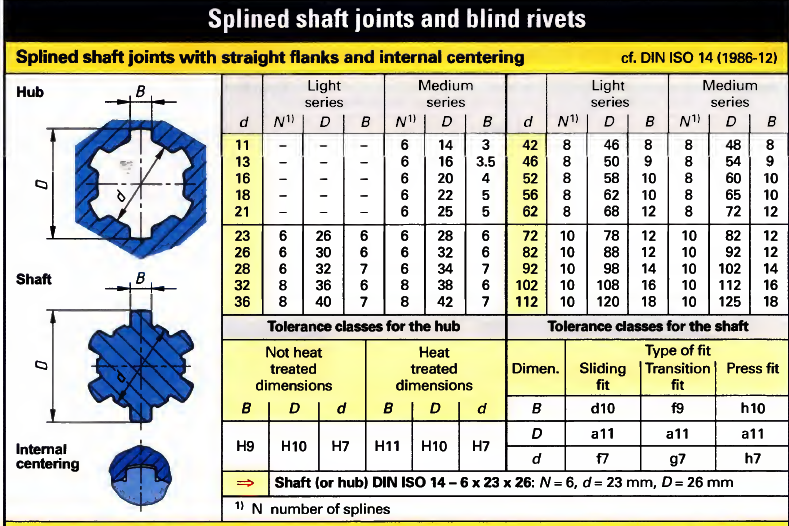MMTH

T_max = [10e3 1e3 0.1e3]; % max torque 
d = [82e-3 42e-3 42e-3]; % see above %shaft diameter

N = [10 8 8]; %number of theeth
% D = 92e-3; %medium series outer diameter
D = [92e-3 46e-3 46e-3]; %light series outer diameter
% Medium series for 10 kNm % light would be 88
B = [12 8 8]; %width of tooth

L = [50e-3 30e-3 25e-3]; %length of spline interacion
r = (D./2 - (D-d)./2)

r =     0.0410    0.0210    0.0210


F = T_max ./ r

F = 1.0e+05 *

    2.4390    0.4762    0.0476


r_fillet = 0.0004;
chamfer = 0.0004;
A = (D-d - r_fillet - chamfer)./2 .* L %area in contact with the spline

A = 1.0e-03 *

    0.2300    0.0480    0.0400



S_Pa = F ./ (A .* N); % Normal stresses
S_MPA =S_Pa /1e6

S_MPA =   106.0445  124.0079   14.8810


Spline holds on Light series

Made medium series for 10 kNm should proably also be made for 1kNm

Stresses in m4 hole

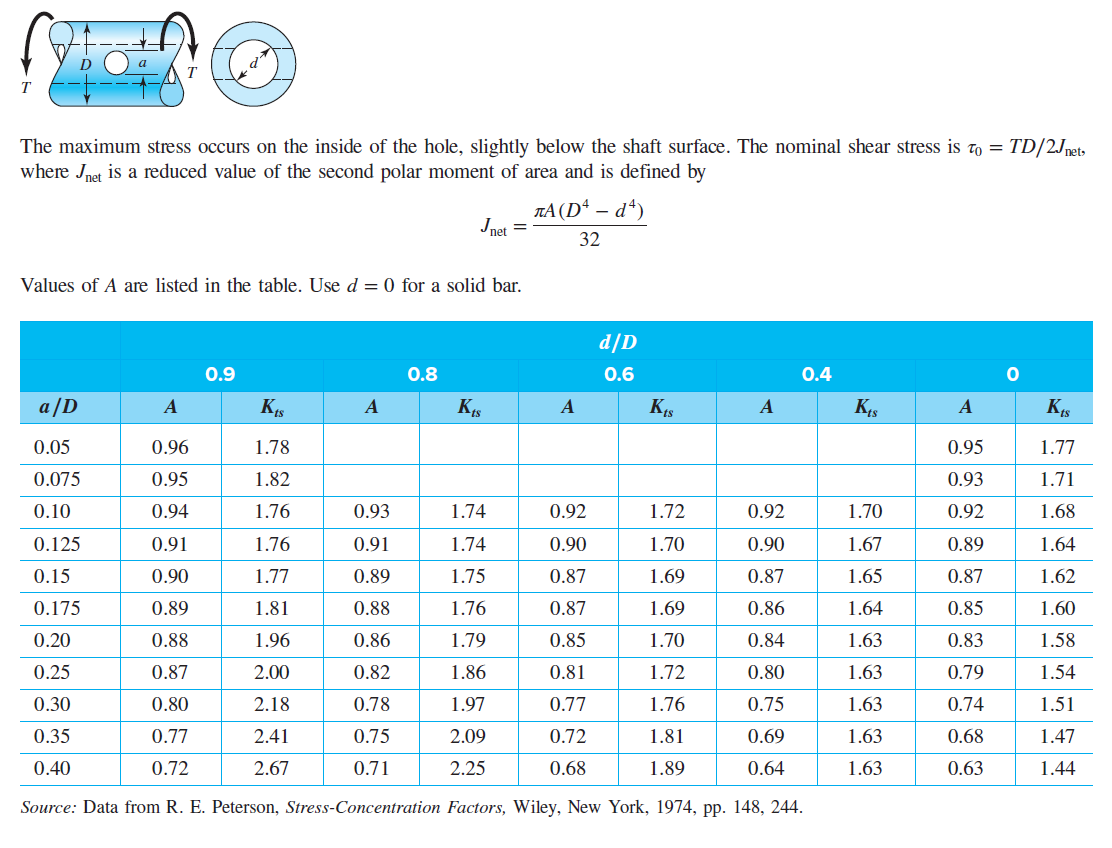

d_p = (D - d)/2 + d

d_p =     0.0870    0.0440    0.0440


m = d_p./N

m =     0.0087    0.0055    0.0055



c = 0.07 *m

c = 1.0e-03 *

    0.6090    0.3850    0.3850


a = 4e-3;
D = [82e-3 42e-3 42e-3]; %light series outer diameter
a_D = a./D

a_D =     0.0488    0.0952    0.0952



d = [42e-3 33e-3 33e-3] ; % inner diameter
d_D = d./D

d_D =     0.5122    0.7857    0.7857


A = [1 0.93 0.93]

A =     1.0000    0.9300    0.9300



J_net = pi .* A .* (D.^4 - d.^4) ./ 32

J_net = 1.0e-05 *

    0.4133    0.0176    0.0176


tau_0 = T_max .* D ./ (2 * J_net);
tau_0_MPa = tau_0 /1e6

tau_0_MPa =    99.1966  119.4348   11.9435


Torque transfer

see FEM

Bolt pretenstion

For M4

S_y = 340e6; % Table 8-11 M4 class 4.8
A_t = 8.78e-6; % tensile strength cross section area
d_bolt = 0.004; % m10

S_p = 0.85 * S_y; % proff strength
F_p = S_p * A_t; % proff force
F_i_m4 = 0.75 * F_p % n_bolts% nonperm

F_i_m4 = 1.9031e+03

T = 0.2 * F_i_m4 * d_bolt % tightning torque

T = 1.5225

M16 M10 M8

clear
%M16 10.9 M10 10.9 M8 10.9
f = 0.18;
S_y = 940e6; %yield strength
A_t = [157 58 36.6]*1e-6; % tensile strength cross section area
d_bolt = [0.016 0.010 0.008]; % m10

S_p = 0.85 * S_y; % proff strength
F_p = S_p * A_t; % proff force
F_i = 0.75 * F_p % n_bolts% nonperm

F_i = 1.0e+04 *

    9.4082    3.4756    2.1933



M = 0.2 * F_i .* d_bolt % tightning torque

M =   301.0632   69.5130   35.0921


Shear force from torque

T_max = [10e3 1e3 0.1e3];
r_max = [98 50.75 42]/1e3;
n_bolts = [8 8 6];% number of bolts
F_i_tot = F_i .* n_bolts;
F_ifric = F_i_tot * f

F_ifric = 1.0e+05 *

    1.3548    0.5005    0.2369


F_s = T_max ./ r_max

F_s = 1.0e+05 *

    1.0204    0.1970    0.0238


Centrifugal force on stop blocks

RPM = 7200;
omega = RPM / 60 * 2 * pi % angualr speed rad/s

omega = 753.9822

r = 0.0245; %distance to center of mass
a = r*omega^2

a = 1.3928e+04

m = 0.0073;
F = a * m

F = 101.6743

Centrifugal force on M16 M10 M8 bolts

m = [0.140 0.055 0.025]; %kg % the aproximate mass of a M10 bolt
%M16x55 M10x50 M8x35 %bolts + washer and nut aproximate
% https://boltport.com/weights/iso-4762/ weigth cahrt
r = r_max

r =     0.0980    0.0508    0.0420


a = r*omega^2

a = 1.0e+04 *

    5.5712    2.8851    2.3877


F_bolt = a .* m

F_bolt = 1.0e+03 *

    7.7997    1.5868    0.5969


l = 0.030; % length of bolt in contact with flange
t = 0.00875; % thickness of metal
tau_bolt = F_bolt / (l*t) /1e6

tau_bolt =    29.7130    6.0449    2.2740


Advanced bolt pretension calculation with shigleys

% P = 10 * u.kN; % ydre last
d = d_bolt%10 * u.mm; % spindeldiameteren

d =     0.0160    0.0100    0.0080


p = [2 1.5 1.25]*1e-3% * u.mm; %pitch (afstand fra top til top)

p =     0.0020    0.0015    0.0013


A_r = [144 52.3 32.8]*1e-6% * u.mm^2; %areal fra roddiameter se table 8-1 i shigleys eller one note

A_r = 1.0e-03 *

    0.1440    0.0523    0.0328


d_r = sqrt(4 * A_r / pi);% rod diameteren
d_m = (d + d_r)/2; %middeldiameter

d_c_min = [17 10.5 8.4]*1e-3% * u.mm; %mindste diameter på spændeskive

d_c_min =     0.0170    0.0105    0.0084


d_c_max = [30 20 16]*1e-3% * u.mm; %største diameter på spændeskive

d_c_max =     0.0300    0.0200    0.0160


% ISO 7090 (2000-11) washer % hardness 300 for class 10.9 (page 239 MMTH)
% 
d_c =  (d_c_min + d_c_max) / 2;%middel diameter på spændeskive

f = 0.18; %friktionskoefficienten i gevind
fc = 0.14; %friktionskoefficienten i spændeskive
% from table 8-5 and 8-6
alpha = 30; %grader %30 grader er den typiske vinkel

n = 1; %antal gevind start
l = p * n; %stigning r omdrejning (l = p ved n = 1)

lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind
vpa(lambda);

%funktion for forspændingsmomentet
T = (F_i .* d_m/2) * ((tan(lambda) + f * secd(alpha)) /...
    (1 - f * tan(lambda) * secd(alpha))) + (F_i * fc .* d_c)/2

T =   333.6434   77.7272   39.1459


M

M =   301.0632   69.5130   35.0921


diffrens = (T - M)./T *100 % forskellen i procent

diffrens =     9.7650   10.5680   10.3556


**Other thingsthat could be usefull**

DIN 5480-16 2006

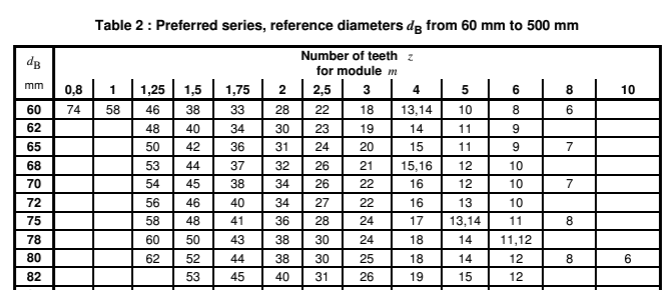

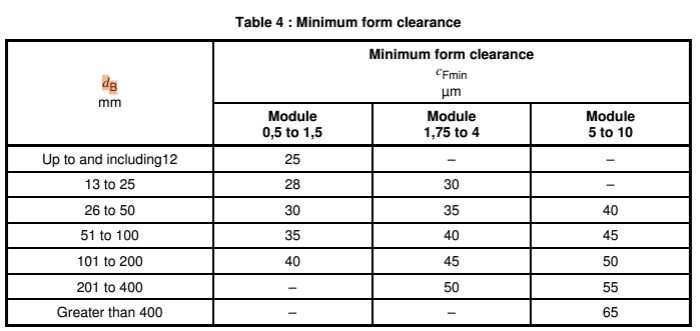

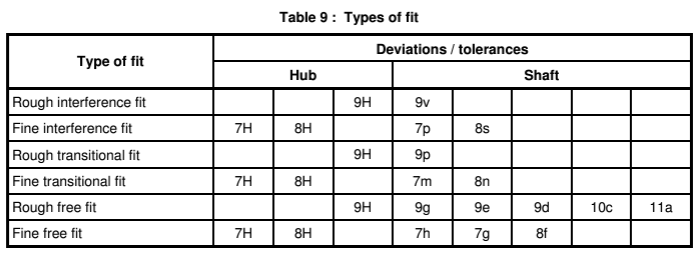

shaft 9e

hub 9H

se side 103 i den blå